clear, clc, close all;
A = rand(5,3);
[Q_qr,R_qr] = qr(A)

Q_qr =   -0.692129588384327   0.545807142831504  -0.444543649874746  -0.157697138043812  -0.023743456485568
  -0.576063996415571  -0.062991233213817   0.735385687553139   0.193102913469048   0.293430625401791
  -0.211871927116904  -0.325533447550389   0.211298154628260  -0.709910430747763  -0.548195705192904
  -0.363649846128877  -0.607069298238388  -0.349194657092734   0.526836461606092  -0.315803880164661
  -0.109434824561821  -0.472886359535376  -0.308228835780523  -0.395364895382045   0.716298886241931


R_qr =   -1.371546928718162  -0.784463910658945  -0.772838831373092
                   0  -0.429068285971798  -0.459065220739614
                   0                   0   0.348746461030720
                   0                   0                   0
                   0                   0                   0


[W,R] = house(A);
Q = formQ(W)

Q =   -0.692129588384327  -0.576063996415571   0.352051196015302   0.064007203688798   0.247123325845214
   0.545807142831504  -0.062991233213817   0.773168570459601   0.226142968428539   0.221802585323295
   0.141967304905808  -0.345543119619195   0.237422962446079  -0.695535251386274  -0.565956082928681
   0.287089632206068  -0.626630851251725  -0.313388899715350   0.549867047257780  -0.352628625064014
   0.347096561686539  -0.390020647293573  -0.351693121166995  -0.398295593906477   0.667143492772424


det(Q)

ans =   -1.000000000000000


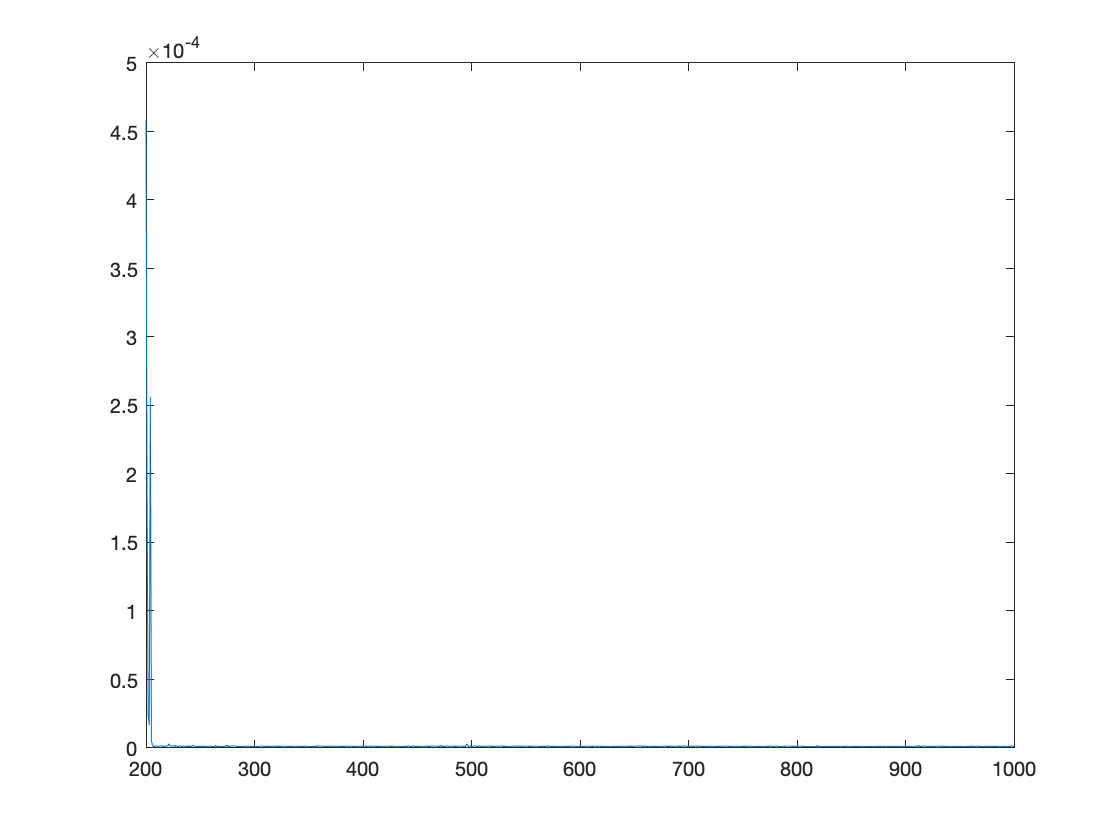

% T_m stores the running time for different m (n fixed)
T_m = zeros(1,20);
m = linspace(200,1000,800);
for i = 201:1000
    A = rand();
    tic
    %[W1, R1] = house(A);
    qr(A);
    T_m (i-200) = toc;
end

T_m;
plot(m, T_m)

function [W, R] = house(A)

% Input: A is a mxn matrix, where m >= n --- This is the matrix we want to
% factorize
% Output: 
% - W is a mxn lower triangular matrix whose column vectors v_k
% defining the successive Householder reflections; 
% - R is a nxn triangular matrix. 

    % Get the size of the matrix A
    [m,n] = size(A);
    W = zeros(m,n);

    for k = 1:n 
        % get each column vector and store it in x
        x = A(k:m,k);
        % elementary basis  
        e = @(i,n) [zeros(i-1,1);1;zeros(n-i,1)]; 
        % reflection vector
        v_k = sign(x(1)) * norm(x) * e(1,m-k+1) + x; 
        % normalized reflection vector
        v_k = v_k/norm(v_k); 
        % store v_k in W
        W(:,k) = [zeros(k-1,1); v_k];
        % produce R by Q_k*A, leave the result in A
        A(k:m,k:n) = A(k:m,k:n) - 2 * v_k * (v_k' * A(k:m,k:n)); 
    end
    
    R = A(1:n,:);
    
end


function Q = formQ(W)

    % Input: W --- mxn lower triangular matrix, produced by house(A) 
    % Output: Q --- mxm matrix, where A = QR
    [m,n] = size(W);
    Q = eye(m);
    for k = 1:n
        % get the kth column as v_k
        v_k = W(:,k); 
        Q = Q - 2 * v_k * (v_k' * Q);
        Q = Q';
    end
end